## alpha

alpha = 0.05;

## Data 1

data_1 = load('experiment_1.mat');
samples_1 = data_1.delta_battery.("mean random") * 100;
samples_2 = data_1.delta_battery.("mean auction") * 100;

figure
histogram(samples_1,20)
hold on
histogram(samples_2,20)
xlabel("Battery usage (%)",'FontSize',14)
ylabel("Frequency",'FontSize',14)
legend('Random selection', 'Auction-based selection','FontSize',14)
ax = gca; exportgraphics(ax,"exp_1.eps")

[p,h,stats] = ranksum(samples_1,samples_2,"Alpha",alpha,'Tail',"both");
if(h == 1)
    fprintf("Ranksum: Null hypothesis rejected. They are two different distributions\n p = %2.4f.  \n",p);
else
    fprintf("Ranksum: Null hypothesis accepted. They are the same distribution\n p = %2.4f. \n",p);
end

Ranksum: Null hypothesis rejected. They are two different distributions
 p = 0.0135.  


fprintf("Random: Mean: %2.2f, Median: %2.2f.\n", mean(samples_1), median(samples_1));

Random: Mean: 13.76, Median: 13.73.


fprintf("Auction: Mean: %2.2f, Median: %2.2f.\n", mean(samples_2), median(samples_2));

Auction: Mean: 13.59, Median: 13.55.


mean(samples_2)-mean(samples_1)

ans = -0.1711

median(samples_2)-median(samples_1)

ans = -0.1807

% [h,p,ci,stats] = ttest2(samples_1,samples_2,"Alpha",alpha,'Tail',"both",'Vartype',"unequal");
% if(h == 1)
%     fprintf("t-student: Null hypothesis rejected. They are two different distributions\n p = %2.4f, confidence interval = [%2.5f, %2.5f] \n",p,ci(1),ci(2));
% else
%     fprintf("t-student: Null hypothesis accepted. They are the same distribution\n p = %2.4f, confidence interval = [%2.5f, %2.5f] \n",p,ci(1),ci(2));
% end

## Data 2

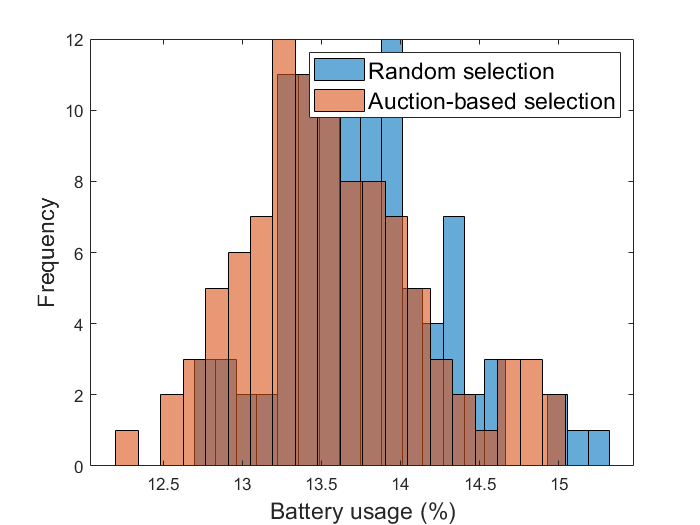

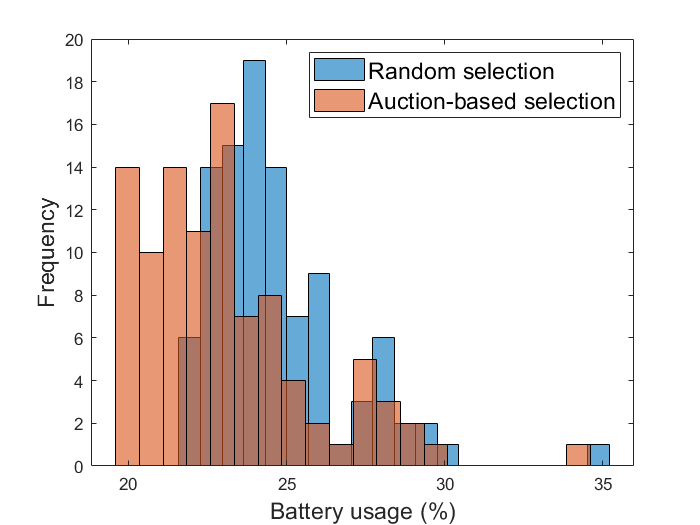

data_2 = load('experiment_2.mat');
samples_1 = data_2.delta_battery.("mean random") * 100;
samples_2 = data_2.delta_battery.("mean auction") * 100;

figure
histogram(samples_1,20)
hold on
histogram(samples_2,20)
legend('Random selection', 'Auction-based selection','FontSize',14)
xlabel("Battery usage (%)",'FontSize',14)
ylabel("Frequency",'FontSize',14)
ax = gca; exportgraphics(ax,"exp_2.eps")


[p,h,stats] = ranksum(samples_1,samples_2,"Alpha",alpha,'Tail',"both");
if(h == 1)
    fprintf("Ranksum: Null hypothesis rejected. They are two different distributions\n p = %2.4f.  \n",p);
else
    fprintf("Ranksum: Null hypothesis accepted. They are the same distribution\n p = %2.4f. \n",p);
end

Ranksum: Null hypothesis rejected. They are two different distributions
 p = 0.0000.  


fprintf("Random: Mean: %2.2f, Median: %2.2f.\n", mean(samples_1), median(samples_1));

Random: Mean: 24.67, Median: 24.14.


fprintf("Auction: Mean: %2.2f, Median: %2.2f.\n", mean(samples_2), median(samples_2));

Auction: Mean: 23.13, Median: 22.67.


mean(samples_2)-mean(samples_1)

ans = -1.5395

median(samples_2)-median(samples_1)

ans = -1.4745

% 
% [h,p,ci,stats] = ttest2(samples_1,samples_2,"Alpha",alpha,'Tail',"both",'Vartype',"unequal");
% if(h == 1)
%     fprintf("t-student: Null hypothesis rejected. They are two different distributions\n p = %2.4f, confidence interval = [%2.5f, %2.5f] \n",p,ci(1),ci(2));
% else
%     fprintf("t-student: Null hypothesis accepted. They are the same distribution\n p = %2.4f, confidence interval = [%2.5f, %2.5f] \n",p,ci(1),ci(2));
% end



## Data 3

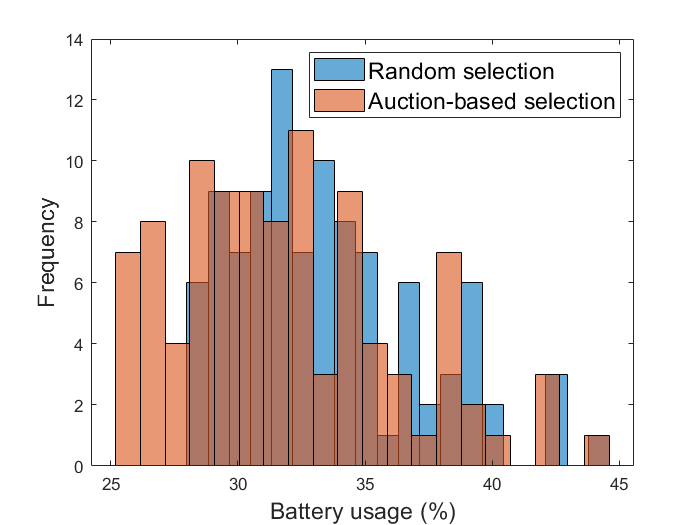


data_3 = load('experiment_3.mat');
samples_1 = data_3.delta_battery.("mean random") * 100;
samples_2 = data_3.delta_battery.("mean auction") * 100;

figure
histogram(samples_1,20)
hold on
histogram(samples_2,20)
legend('Random selection', 'Auction-based selection','FontSize',14)
xlabel("Battery usage (%)",'FontSize',14)
ylabel("Frequency",'FontSize',14)
ax = gca; exportgraphics(ax,"exp_3.eps")

[p,h,stats] = ranksum(samples_1,samples_2,"Alpha",alpha,'Tail',"both");
if(h == 1)
    fprintf("Ranksum: Null hypothesis rejected. They are two different distributions\n p = %2.4f.  \n",p);
else
    fprintf("Ranksum: Null hypothesis accepted. They are the same distribution\n p = %2.4f. \n",p);
end

Ranksum: Null hypothesis rejected. They are two different distributions
 p = 0.0042.  


fprintf("Random: Mean: %2.2f, Median: %2.2f.\n", mean(samples_1), median(samples_1));

Random: Mean: 33.48, Median: 32.62.


fprintf("Auction: Mean: %2.2f, Median: %2.2f.\n", mean(samples_2), median(samples_2));

Auction: Mean: 31.96, Median: 31.26.


mean(samples_2)-mean(samples_1)

ans = -1.5188

median(samples_2)-median(samples_1)

ans = -1.3617


% [h,p,ci,stats] = ttest2(samples_1,samples_2,"Alpha",alpha,'Tail',"both",'Vartype',"unequal");
% if(h == 1)
%     fprintf("t-student: Null hypothesis rejected. They are two different distributions\n p = %2.4f, confidence interval = [%2.5f, %2.5f] \n",p,ci(1),ci(2));
% else
%     fprintf("t-student: Null hypothesis accepted. They are the same distribution\n p = %2.4f, confidence interval = [%2.5f, %2.5f] \n",p,ci(1),ci(2));
% end



## Analysis with all robots, no mean

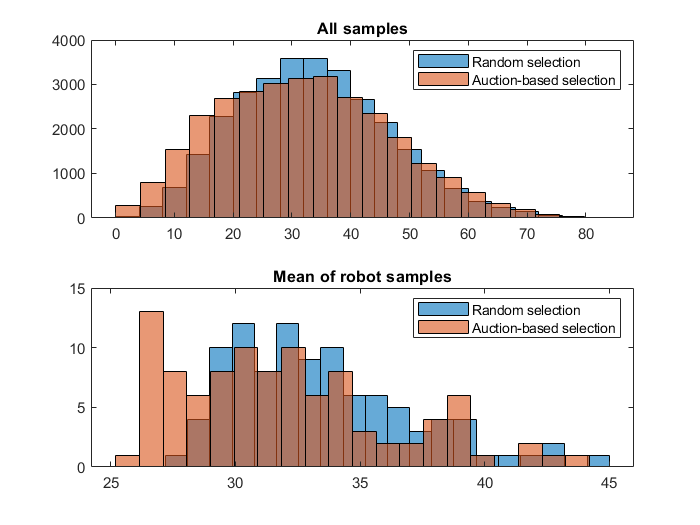

load("experiment_3_all_agents.mat")
for i = 1:length(delta_battery)
    random(i,:) = delta_battery{i}.random*100;
    auction(i,:) = delta_battery{i}.auction*100;
end




% Plotting the distribution of a single row
nbins = 20;
figure
subplot(2,1,1)
h1 = histogram(random(:),nbins);
hold on
h2 = histogram(auction(:),nbins);
legend('Random selection', 'Auction-based selection')
title("All samples")

% Plotting the distribution of the mean
random_mean = mean(random,2);
auction_mean = mean(auction,2);


subplot(2,1,2)
h1 = histogram(random_mean,nbins);
hold on
h2 = histogram(auction_mean,nbins);
legend('Random selection', 'Auction-based selection')
title("Mean of robot samples")